# smFISH検出

**使い方** (ショートカットコマンドはmacの場合のものなのでwindowsは違うかも) (上のメニューから同様のことができる)

解析したいデータ(蛍光もROIも)をRawDataフォルダに入れてもらって、下のドロップダウンから選択する

基本的に上から順に実行していく(「実行して次にすすむ」もしくはshift & command & enter)

 (一括で行いたい場合は「実行」もしくは option & command & enter)

パラメータなどの変更が終わったらそれ以下の部分も実行すること(変更した中で一番上のブロックに入力カーソルを移動して上のメニューの「最後まで実行」)

**お願い**

いくつかのデータで遊んでもらって、シグナルを捉えられていると考えられる適切なパラメータを決めて欲しいです

## コードの読み込み準備

addpath(genpath("functions"))
datafiles = string({dir("RawData").name});
figNameList = datafiles(contains(datafiles, ".tif"));
ROINameList = datafiles(contains(datafiles, ".zip"));

## どのデータを解析するか

% 画像データを選ぶ
figFilename = figNameList(1);
% ROIデータを選ぶ
ROIFilename = ROINameList(1);

## データを取り込む

tifData = readTifSeq(append("RawData/", figFilename));
tmrData = tifData(1:2:end,:,:);
figSize = size(tifData, 3);
ROIs = readROIs(append("RawData/", ROIFilename), figSize);
Npages = size(tifData, 1)/2;

## parameters set

% 周辺の輝度規格化に使用するボールの大きさ [pixel] だんだん小さくする
discSize_step1 = 10; % 初期値10
default_discSize_step2 = min(7, discSize_step1);
discSize_step2 = 7;% 初期値7
default_discSize_step3 = min(5, discSize_step2);
discSize_step3 = 5;% 初期値5
% ガウシアンフィルターの大きさ [pixel] だんだん大きくする
filterSize_step1 = 1; % 初期値1
default_filterSize_step2 = max(5, filterSize_step1);
filterSize_step2 = 7; % 初期値1
% 輝度の上位どれだけの割合をシグナルとみなすか
top_proportion = 0.005; % 初期値0.005
% 何pixel以上をシグナルとみなすか
pixel_threshold = 4; % 初期値4

param = [discSize_step1, filterSize_step1, discSize_step2, filterSize_step2, discSize_step3, top_proportion, pixel_threshold];

## ROIの確認

% 何ページ目を解析するか
page = 18;

% 元の画像
disp("元の画像")

元の画像


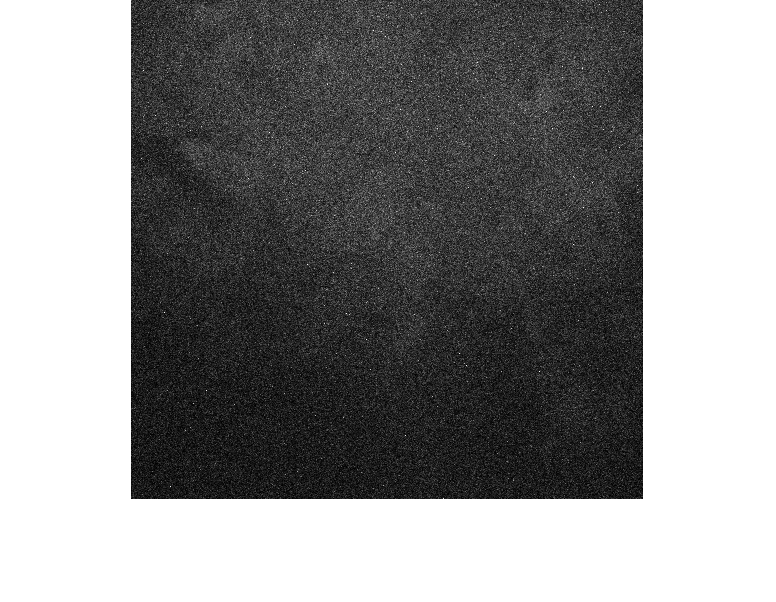

imshow(rescale(double(squeeze(tmrData(page,:,:)))))


% ROIを重ねる
disp("ROI")

ROI


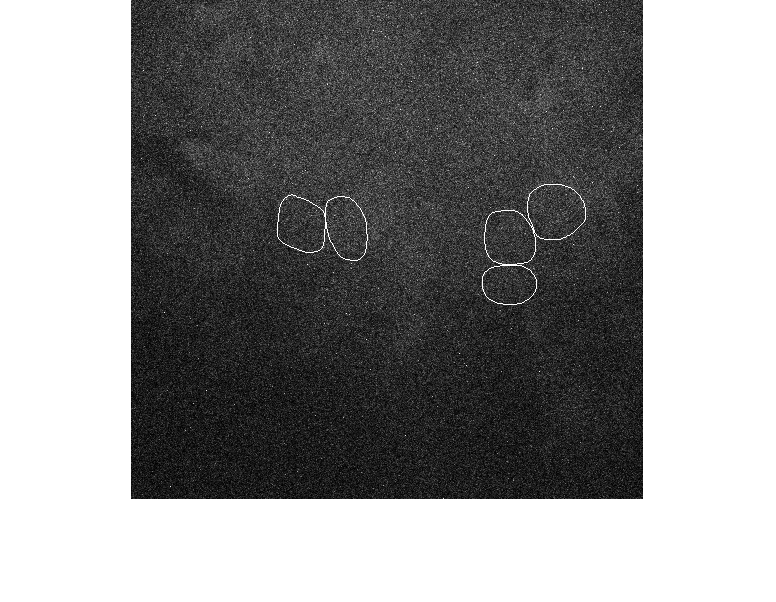

ROIBoundaries = zeros(figSize, "logical");
for i = 1:size(ROIs, 1)
    ROIBoundariesIndex = bwboundaries(squeeze(ROIs(i,:,:)));
    ROIBoundaries(sub2ind([figSize, figSize], ROIBoundariesIndex{1}(:,1), ROIBoundariesIndex{1}(:,2))) = true;
end
imshow(rescale(double(squeeze(tmrData(page,:,:))))+ROIBoundaries)

## シグナル検出

FP = highlightFP(squeeze(tmrData(page,:,:)), param);
disp("シグナルだけ")

シグナルだけ


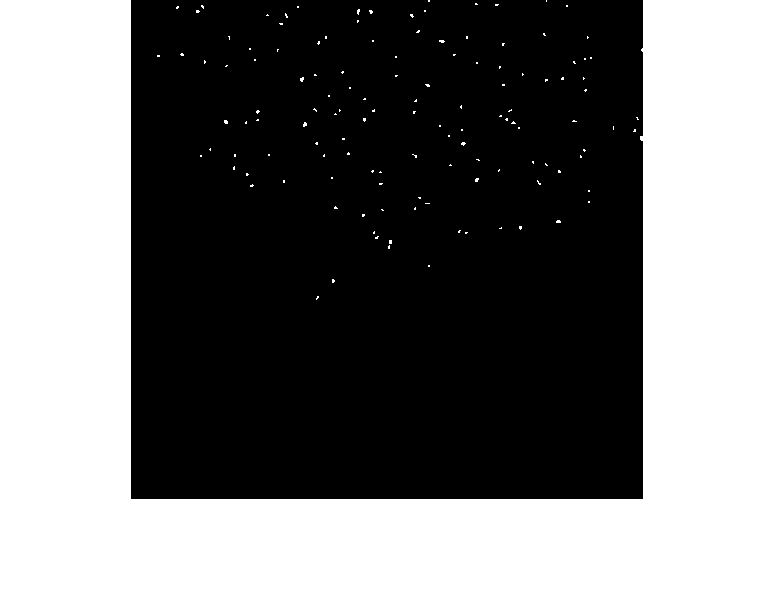

imshow(FP)


colorfig = repmat(rescale(double(squeeze(tmrData(page,:,:)))), 1, 1, 3);
colorfig(:,:,1) = min(colorfig(:,:,1)+ROIBoundaries,1);
colorfig(:,:,2) = min(colorfig(:,:,2)+FP,1);
disp("ROIは赤、シグナルは緑")

ROIは赤、シグナルは緑


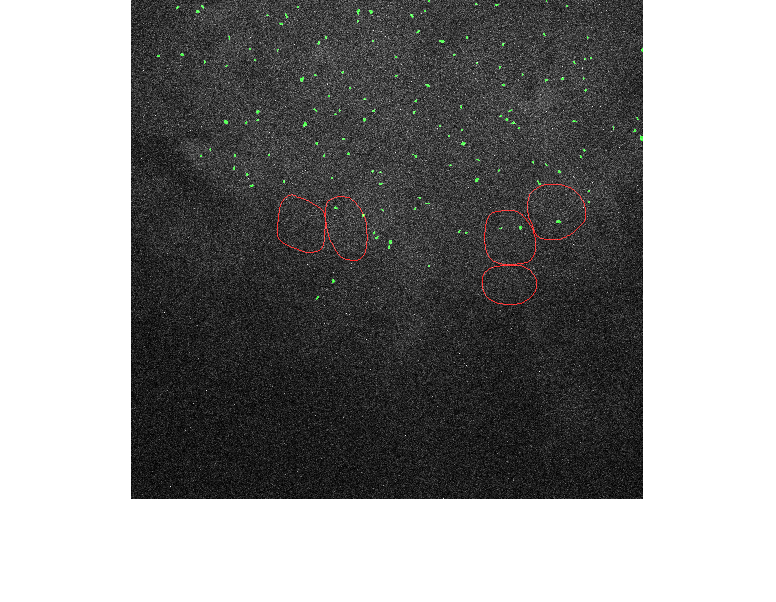

imshow(colorfig)


NsignalInROI = zeros(1,size(ROIs, 1), "uint16");
for i = 1:size(ROIs, 1)
    CC = bwconncomp(squeeze(ROIs(i,:,:)) & FP);
    NsignalInROI(i) = CC.NumObjects;
end
disp("ROI内のシグナル数 : ")

ROI内のシグナル数 : 


disp(NsignalInROI)

   2   1   0   2   0

